x = gpml_randn(0.8, 20, 1);                 % 20 training inputs
y = 3*x + 2*x.^2 + 0.1*gpml_randn(0.9, 20, 1);  % 20 noisy training targets
xs = linspace(-3, 3, 61)';                  % 61 test inputs
% GP nach eigenen Funktionen
theta = [1;1;1];


[theta, logLike] = scaledConjugateGradient(@Error,@DelLogLik,theta,x,y,10^-6 ,10^-4)

Delta = 2.1178

reduce scale
9.


w =     1.6018
    1.0279
    0.9378


r =     7.1313
   -4.4576
   -0.6775


Emin = 36.6968

Delta = 0.4076

9.


w =     2.8266
   -0.2962
    0.8284


r =     1.3408
    2.0326
    1.8953


Emin = 33.6984

Delta = -13.6672

increase scale
9.


w =     2.8266
   -0.2962
    0.8284


r =     1.3408
    2.0326
    1.8953


Emin = 33.6984

theta =     2.8266
   -0.2962
    0.8284


logLike = 33.6984

%theta = [0.9;0.092;0.53];

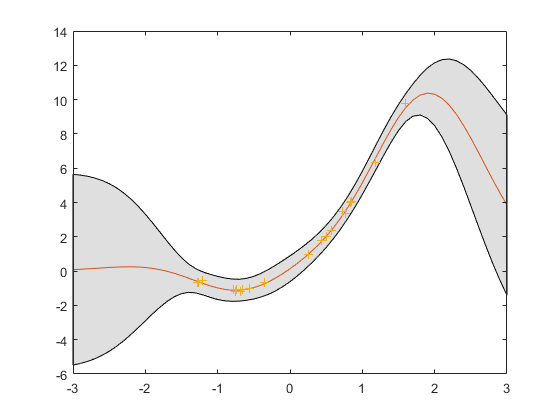


n = length(y);
K = CovMatrix(x,theta(1),theta(3));
K_y = (K + theta(2)^2 * eye(n))^-1;

yPredict = zeros(length(xs),1);
sig = zeros(length(xs),1);

for i = 1: length(xs)
    [yPredict(i),sig(i)] = GPpredict_V1(K_y,x,y,xs(i),theta(1),theta(3));
end
    sig = sig + theta(2)^2;

  f = [yPredict+2*sqrt(sig); flipdim(yPredict-2*sqrt(sig),1)];
  fill([xs; flipdim(xs,1)], f, [7 7 7]/8)
  hold on; 
  plot(xs, yPredict); 
  plot(x, y, '+')
  hold off;

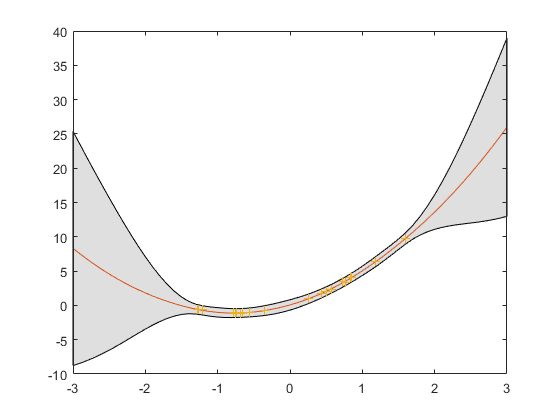

%incorporate xplixit basic fct

    B = [0,0;0,0];
    H = [x.' ; (x.^2).'];
    b= [0;0];
    beta_bar = (B + H * K_y * H.')^-1 *(H*K_y*y+B*b);
    g= zeros(length(xs),1);
    g_cov = g;
    
for i = 1 : length(xs)
    H_s =[xs(i); xs(i)^2];
    K_s = zeros(n,1);
    for j = 1 : n
         K_s(j) = kernel(x(j,:),xs(i),theta(1),theta(3)); 
    end
    R = H_s - H*K_y*K_s;
    g(i) = H_s.' * beta_bar + K_s.' * K_y * (y - H.' * beta_bar);
    g_cov(i) = (kernel(xs(i),xs(i),theta(1),theta(3)) - K_s.'* K_y * K_s) + R.'*(B+ H* K_y*H.')^-1 * R+ theta(2)^2;
end

  f = [g+2*sqrt(g_cov); flipdim(g-2*sqrt(g_cov),1)];
  fill([xs; flipdim(xs,1)], f, [7 7 7]/8)
  hold on; 
  plot(xs, g); 
  plot(x, y, '+')
  hold off;

Funktionen

function DLL = DelLogLik(w,x,y)
    n = length(y);
    delK = zeros (n,n,3);
    DLL = zeros(3,1);
    
    K = CovMatrix(x,w(1),w(3))+eye(n);
    
    %Del K berechnen
    delK(:,:,2) = 2 * w(2) * eye(n);
    
    for i = 1 : n
        for j = 1: n
        d =(x(i,:)-x(j,:)) * ((x(i,:)-x(j,:)).');
        
        delK(i,j,1) = 2* w(1)          * exp(-1/(2*w(3)^2)*d);
        delK(i,j,3) =  w(1)^2 * d/w(3)^3 * exp(-1/(2*w(3)^2)*d);
        end
    end
    %K_inv= chol(K+eye(n));
    K_inv= (K+eye(n))^-1;
    a = K_inv*y;
    DLL(1) = -0.5 * trace((a*a.' - K_inv)*delK(:,:,1));
    % Hier Optimierung, da nur diagonale Werte übernommen 
    DLL(2) = -0.5 * trace((a*a.' - K_inv)*delK(:,:,2)); 
    DLL(3) = -0.5 * trace((a*a.' - K_inv)*delK(:,:,3));
end

function E = Error(theta,x,y)
    if length(theta) ==3
        sigmaF = theta(1);
        l = theta(2);
        sigmaN = theta(3);
    else
        sigmaN = theta;
        sigmaF= 1;
        l =1;  
    end
    K = CovMatrix(x,sigmaF,l);
    E = - logLikelihood_V1(y,K,sigmaN);
end
